% This is the completed OFDM simulation code
% over AWGN,  no Doppler and unit channel 
% With unit channel gain
% No pilot symbol/ channel estimation

bits_len = 32

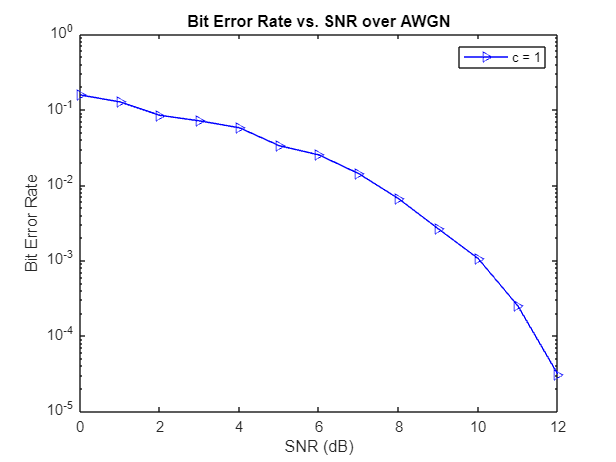


% Parameter definition
total_subchannels = 16;                        % Total number of subchannels

cp_length = total_subchannels / 4;              % cyclic prefix length
modulation_order = 4;                           % Modulation order
channel_length = 1;                             % Channel length
max_iterations = 1000;                             % Number of iterations in each evaluation
SNR_vector = [0:1:15];                          % Signal-to-noise ratio vector in dB
bit_error_rate = zeros(1, length(SNR_vector));  % Initializing bit error rate

bits_len = total_subchannels * log2(modulation_order)


error_bit_count_threshold = 100;

total_bit_error_count_array = zeros(length(SNR_vector),1 );


for snr_index = 1:length(SNR_vector)
    SNR = SNR_vector(snr_index);
    total_bit_error_count = 0;

    for iteration = 1:max_iterations     
        % Generating random channel coefficients
        h = ones(channel_length, 1) * c; % Flat frequency response channel

        % Transmitted Data
        tx_data_bits = randi([0 1], bits_len, 1);
        tx_data_symbols = qammod(tx_data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
        tx_data_ifft = ifft(tx_data_symbols, total_subchannels);
        
        % Add CP
        tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];

        % Transmission through the channel
        rx_data_ifft_with_guard = tx_data_ifft_with_cp; % Assuming no channel effect

        % Adding AWGN noise 
        rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_guard, SNR, 'measured');

        % Remove CP
        rx_data_ifft = rx_data_ifft_with_cp_and_noise(cp_length + 1 : total_subchannels + cp_length);
        rx_data_symbols = fft(rx_data_ifft, total_subchannels);

        % Demodulation
        rx_data_symbols_demap = rx_data_symbols; % No channel effect
        rx_data_bits = qamdemod(rx_data_symbols_demap, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count = sum(rx_data_bits ~= tx_data_bits);
        total_bit_error_count = total_bit_error_count + bit_error_count ;
        if total_bit_error_count >= error_bit_count_threshold
            break
        end    
    end
    ber = total_bit_error_count / (iteration * bits_len);
    total_bit_error_count_array(snr_index, c) = ber;
end

% Plotting
figure;
semilogy(SNR_vector, total_bit_error_count_array, 'b->');

xlabel('SNR (dB)');
ylabel('Bit Error Rate');
title('Bit Error Rate vs. SNR over AWGN');
legend('c = 1');